% LOAD the BALL DATA you WANT


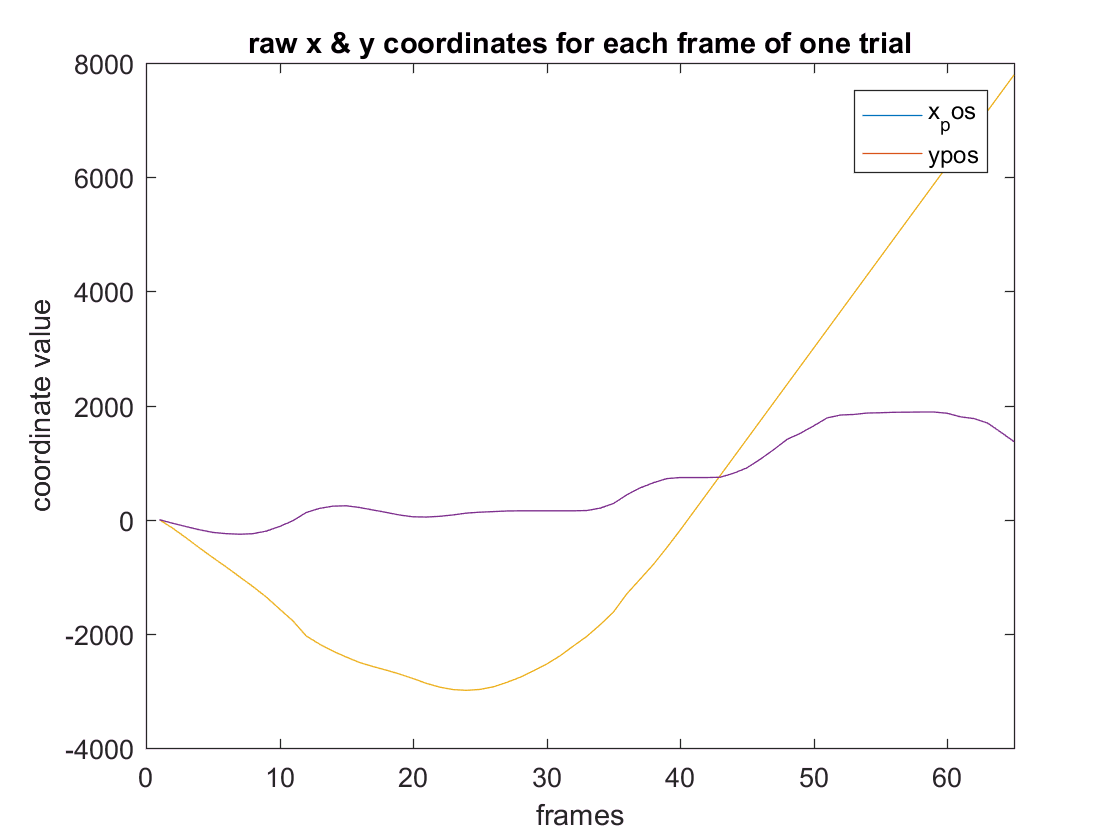

% raw x & y coordinates for each frame of ONE TRIAL

clear allXCoordinates1Trial
clear allYCoordinates1Trial

allXCoordinates1Trial = allResp(3).xpos; % this is the x value at each frame 
% during the firts trial
allYCoordinates1Trial = allResp(3).ypos; % y value at each frame during 1st trial

% want to plot just raw x & y coordinates, need to extract
% values(they are already doubles...

figure
clear i
for i = 1:length(allXCoordinates1Trial) % for each frame 
    % in the 1st trial
    x_axis = 1:length(allXCoordinates1Trial); % x axis same length 
    % as # frames in 1st trial
    plot(x_axis,allXCoordinates1Trial)
    hold on 
    plot(x_axis,allYCoordinates1Trial)
    title('raw x & y coordinates for each frame of one trial')
    xlabel('frames')
    ylabel('coordinate value')
    legend('x_pos','ypos')
    xlim([0 length(allXCoordinates1Trial)])
end

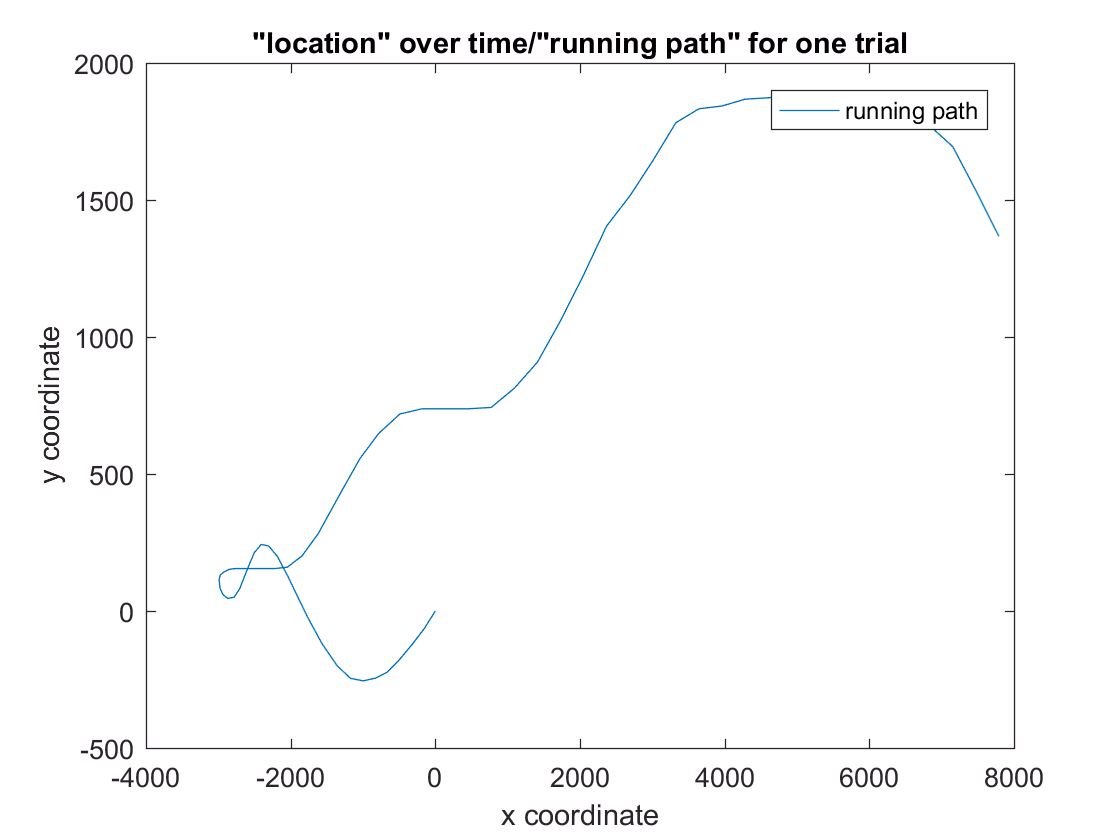

% optical mouse 'position'/"running path" for each frame of ONE TRIAL

% simply plot x vs y to show "location" over time

% plot the x coordinates vs the y coordinates as a line
% this will show the "running path" over time (cursor pattern on screen)
figure
plot(allXCoordinates1Trial,allYCoordinates1Trial)
title('"location" over time/"running path" for one trial')
xlabel('x coordinate')
ylabel('y coordinate')
legend('running path')

% to calulate running speed for ONE TRIAL, i first need to calculate 
% the displacemnt between each frame in the trial
% i can do this with diff(x) and diff(y) - this is how I get the 
% 'length' of dx & dy, and this will also make the origin zero
% then use pythagoreum theorem  to find displacemnt/length of hypotenuse

clear diffX
clear diffY
diffX = diff(allXCoordinates1Trial);
diffY = diff(allYCoordinates1Trial);

displacent = sqrt(diffX.^2+diffY.^2);

clear x_axis
x_axis = [1:length(displacent)]

x_axis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


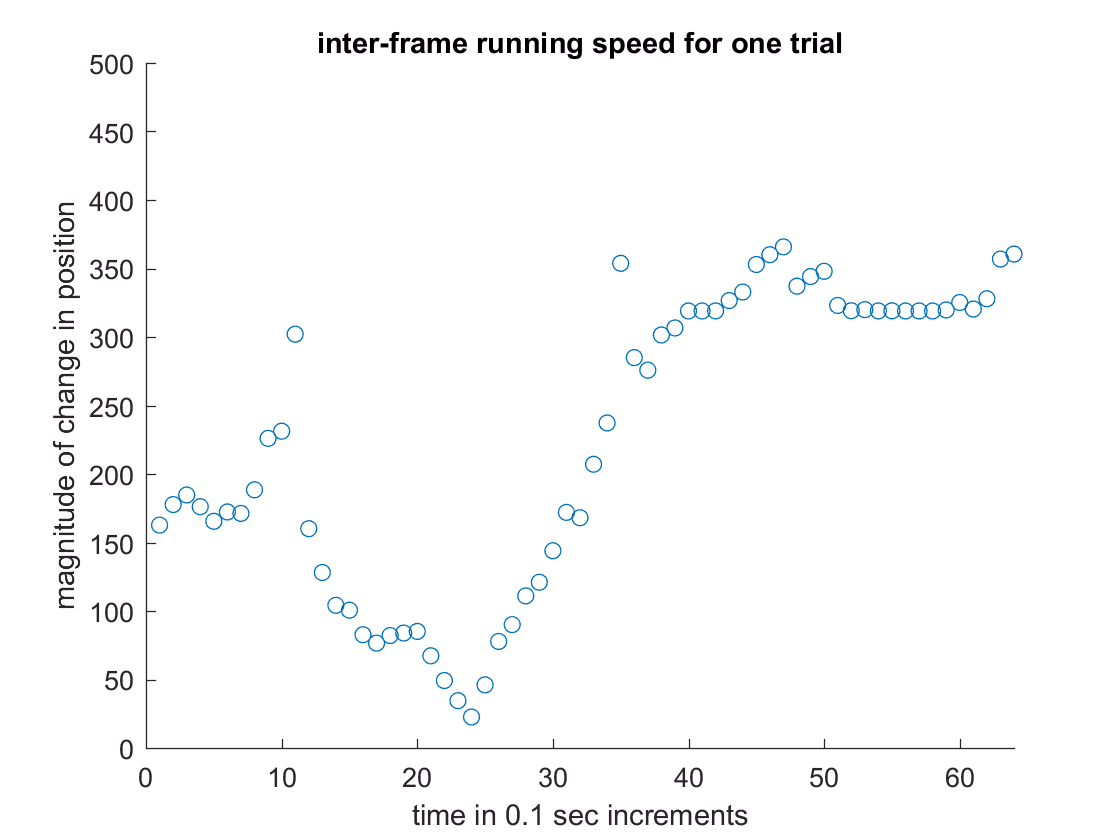

figure
scatter(x_axis,displacent) 
xlabel('time in 0.1 sec increments')
ylabel('magnitude of change in position')
title('inter-frame running speed/displacement for one trial')
xlim([0 length(x_axis)])
ylim([0 500])

% CALCULATE MEAN DISPLACEMENT/RUNNING SPEED for ONE TRIAL
% the running speen on a given trial will be the
% mean displacent for that trial
meanRunningSpeed1Trial = mean(displacent) % units are pixels?

meanRunningSpeed1Trial = 225.3813

% ok now I need to do this whole process (calculate running speed)
% FOR EVERY TRIAL, and have a vector w/mean speed for each trial 
% in a recording session

% for each TRIAL, calulate MEAN RUN SPEED

numTrialsThisSession = length(allResp)

numTrialsThisSession = 2115


clear meanSpeedAllTrials % clear each session's final
% mean speed per trial vector

% for each TRIAL, calulate MEAN RUN SPEED
clear tr
for tr = 1:length(allResp) % for each row/trial in the allResp struct array
% for tr = 1   
    % extract x & y coordinate value for each frame in tthe tr-th trial
    clear allXCoordinatesTthTrial % clear - note that there's a new number 
    % of frames/coordinates trial
    clear allYCoordinatesTthTrial
    allXCoordinatesTthTrial = allResp(tr).xpos; % this is the x value at each frame 
    % during the firts trial
    allYCoordinatesTthTrial = allResp(tr).ypos;
    size(allYCoordinatesTthTrial); % this shows # frames in each trial
    
    % calculate displacement between each frame
    clear tr_thDiffX
    clear tr_thDiffY
    tr_thDiffX = diff(allXCoordinatesTthTrial);
    tr_thDiffY = diff(allYCoordinatesTthTrial);
    tr_thDisplacement = sqrt(tr_thDiffX.^2+tr_thDiffY.^2); % P. Theorem
    size(tr_thDisplacement); % should be = # frames-1
    
    % now, the running speed on a given trial will be the
    % mean displacent for that trial    
    clear tr_thMeanSpeed
    tr_thMeanSpeed = mean(tr_thDisplacement,2); % units are pixels?
    
    % store the mean speed for each trial in a cell in a vector
    meanSpeedAllTrials(1,tr) = tr_thMeanSpeed;
    % should have 1 x # trials vector w/mean speed of each trial in each cell
    
end % end trials loop

% to check speed calc'd for each trial
numTrialsWithRunSpeedCalculated = length(meanSpeedAllTrials)

numTrialsWithRunSpeedCalculated = 2115

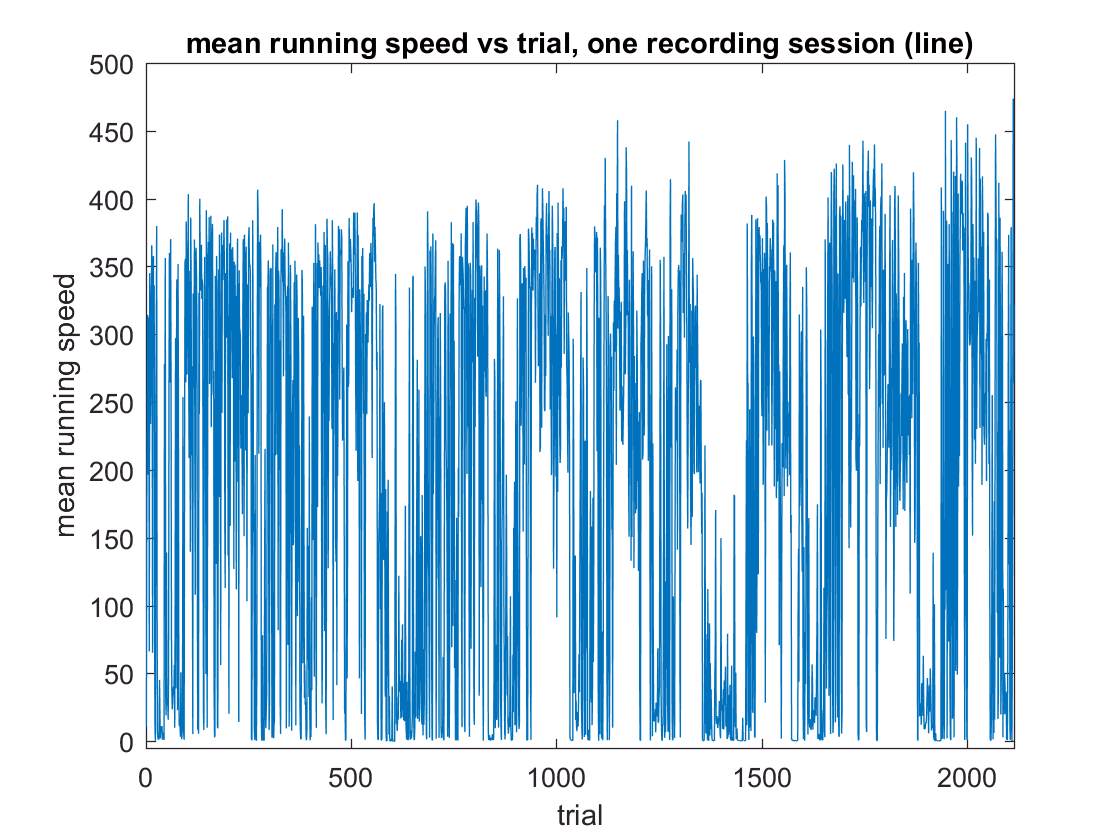


% PLOT the running speed over trials/time for this session
figure
clear x_axis
x_axis = [1:length(meanSpeedAllTrials)]; % number of trials
% plot mean speed vs trials
plot(x_axis,meanSpeedAllTrials)
xlabel('trial')
ylabel('mean running speed')
title('mean running speed vs trial, one recording session (line)')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])

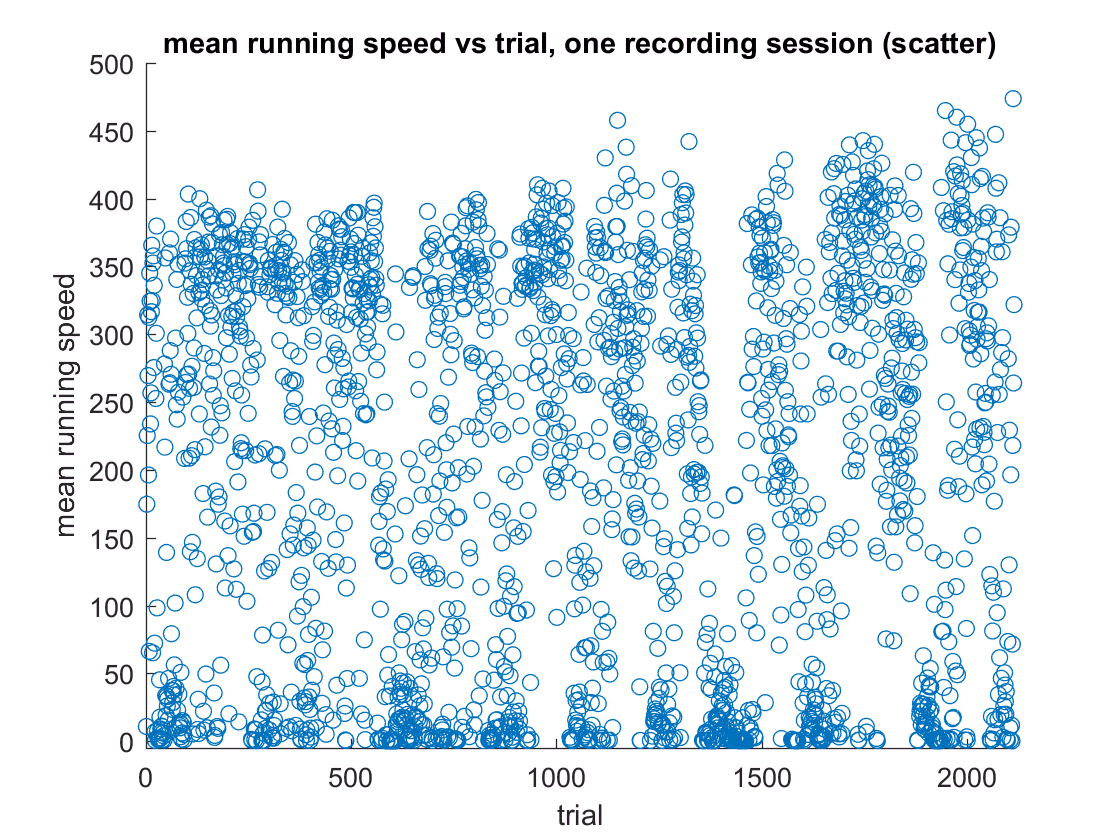


figure
clear x_axis
x_axis = [1:length(meanSpeedAllTrials)];
scatter(x_axis,meanSpeedAllTrials)
xlabel('trial')
ylabel('mean running speed')
title('mean running speed vs trial, one recording session (scatter)')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])

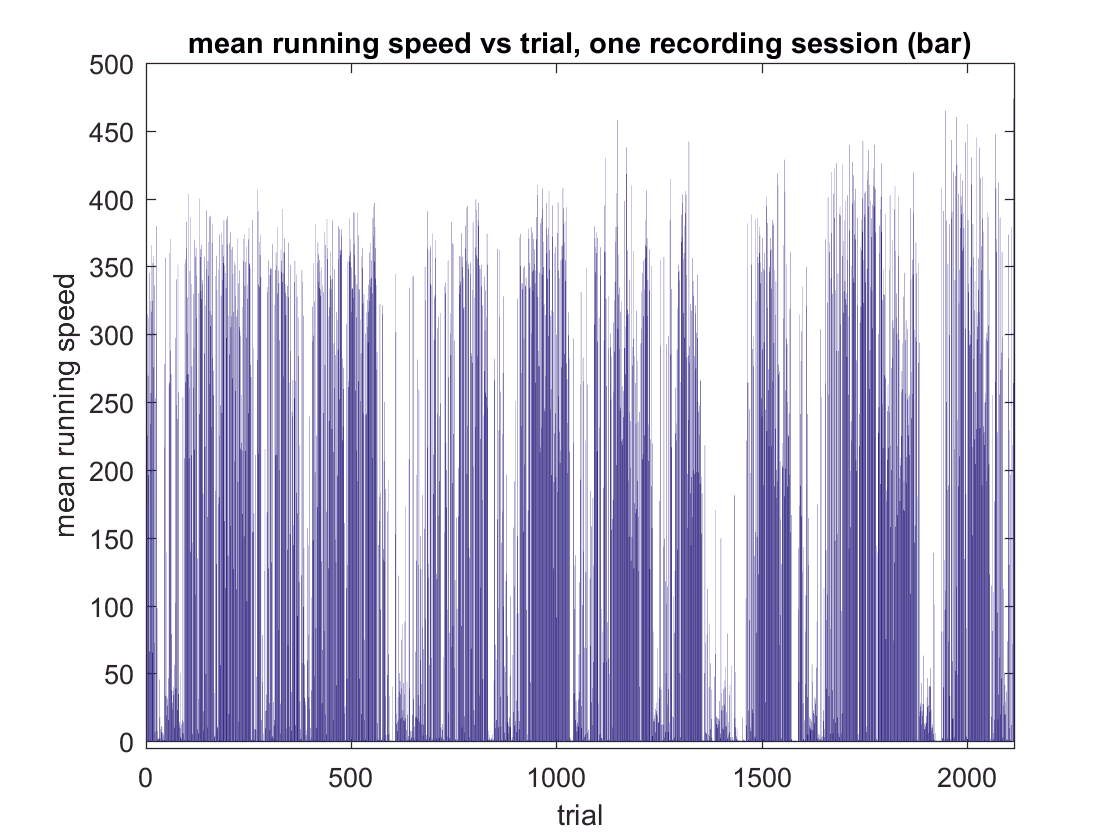


figure
clear x_axis
x_axis = [1:length(meanSpeedAllTrials)];
bar(meanSpeedAllTrials)
xlabel('trial')
ylabel('mean running speed')
title('mean running speed vs trial, one recording session (bar)')
xlim([0 length(meanSpeedAllTrials)])
ylim([-5 500])

% HISTO showing FREQuency of different RUNning SPEEDs for FOR EVERY TRIAL


numTrials = 2115

numBins = 10

numBins = 10

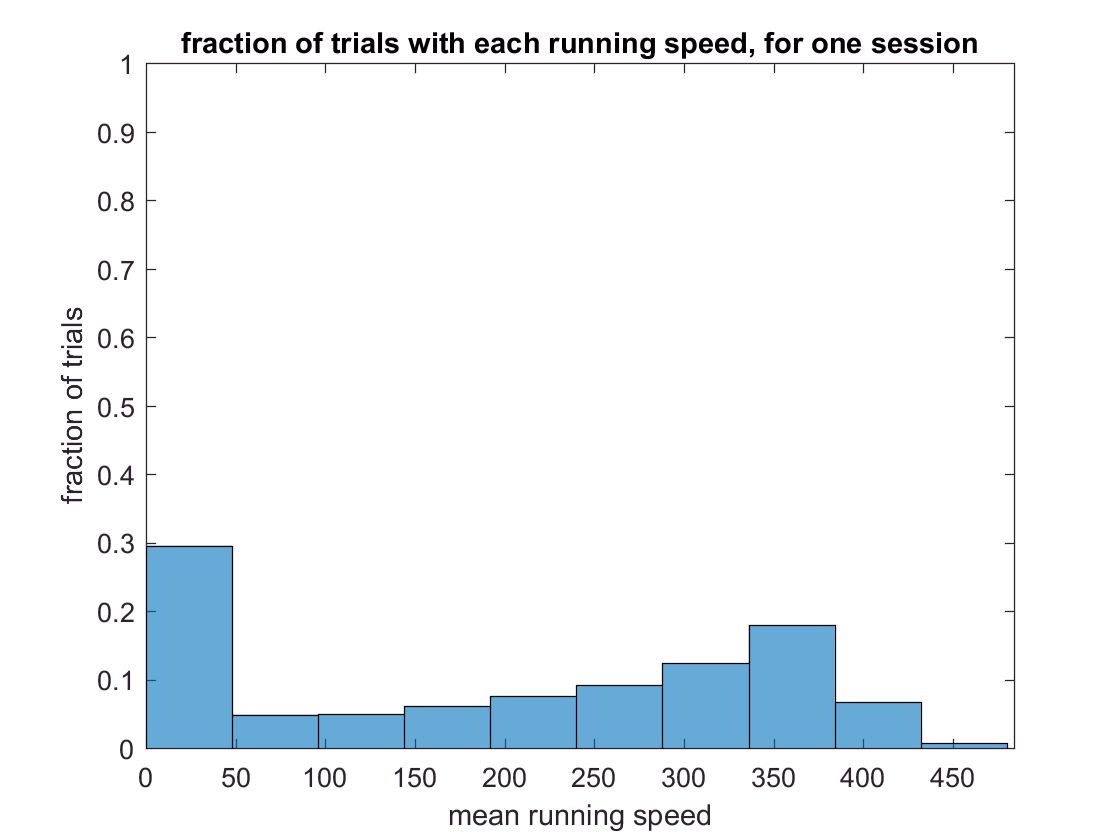


histogram(meanSpeedAllTrials,numBins,'normalization','probability')
ylabel('fraction of trials')
xlabel('mean running speed')
title('fraction of trials with each running speed, for one session')
xlim([0 round(max(meanSpeedAllTrials)+10)])
set(gca,'xtick',0:50:round(max(meanSpeedAllTrials)+10));
ylim([0 1])

% pick a threshold... what percentage of trials above & below it?
% pick 30 pix/frame threshold for running

numTrials = length(meanSpeedAllTrials)

numTrials = 2115


sumTrialsOverThresh = sum(meanSpeedAllTrials>=60)

sumTrialsOverThresh = 1457

percentTrialsOverThresh = (sumTrialsOverThresh/numTrials)*100

percentTrialsOverThresh = 68.8889

sumTrialsUnderThresh = sum(meanSpeedAllTrials<=60)

sumTrialsUnderThresh = 658

percentTrialsUnderThresh = (sumTrialsUnderThresh/numTrials)*100

percentTrialsUnderThresh = 31.1111

ratio_under2over_threshold = 0.4516

% a few different things I want to plot -

% would be nice to have a VARiable to store the overall neural trace at each vis area
% along side the x & y cursor coordinates for the entire recording 

% don't forget - RUN SPEED is a mean taken over all frames in a trial. One run speed per trial...
% DISPLACEMENT is "between frames", so it's got one less frame then the trial really does
% RAW coordinates can be used to visualize speed, probably even with only one dimension (x or y)
% *and* there is a value for each frame of the trial

% PLOT raw coordinates over neural activity for entire recording

% PLOT raw coordinates vs neural response for smaller segments (ex: 1 min each)

% then need another VAR that is the same as above (to store the overall neural trace at each vis area
% along side the x & y cursor coordinates) but for 23 frames only (peri-stim "chunk")

% for each PERI-STIM ONSETS frame range, 
% PLOT neural trace at each vis area and
% overlay the MAGnitude of DISPLACEMENT (just put a zero at the first frame?) 
% and and mark STIM ONSET for each peri-stim chunk

% --> can seperate these traces by trial number, stimulus condition, take means or plot each trial etc

% then SEPERATE TRIALS w/in a session by RUN SPEED
% then PLOT FREQ NEURAL RESPONSE HISTOS SEPERATED by RUN SPEED for V1 (the 23 frames only)


% PLOT raw coordinates over neural activity for entire recording
% NOW we need to COMBINE NEURAL TRACES from PTSdfof(23 frames only)
% with the RAW COORDINATE data

% let's look at how the 23 onset frames are collected...

% --> So, now, it's looking like I might want to combine eye info with dFof info
% earlier, like at the onsets code area, so that it can get 'chunked' just like
% the peri stim frames
% even before the chunk gets defined actually
% save that shit out as "EarlyIndAnlaysisVars'

% how will I save this cursor coordinates + dfof data?
% allX&YCoordinates are a double pulled out of a struct - 
% the length of this var should match the length of frames in the 
% *imaging* session, I hope...
% so the     


% % for one SESSION, concatenate X values & Y values from EVERY TRIAL
% % ALL RESP
% 
% allXCoordinatesAllTrialsOneSessAllResp = []; % empty vector to store all x/y points trials in
% allYCoordinatesAllTrialsOneSessAllResp = [];
% 
% clear tr
% for tr = 1:length(allResp) % for each row/trial in the allResp struct array
% % for tr = 1   
% 
%     % extract x & y coordinate value for each frame in tthe tr-th trial
%     clear allXCoordinatesTthTrialAllResp % clear - note that there's a new number 
%     % of frames/coordinates each trial
%     allXCoordinatesTthTrialAllResp = allResp(tr).xpos; % this is the x value at each frame during
%     % the tr-th trial
%     % not entirely sure the logic behind this but I think basically this
%     % updates the original empty matrix by adding to it each time -
%     % it's like appending a column to the end of the matrix each time:
%     allXCoordinatesAllTrialsOneSessAllResp = [allXCoordinatesAllTrialsOneSessAllResp,allXCoordinatesTthTrialAllResp];
%     
%     clear allYCoordinatesTthTrialAllResp
%     allYCoordinatesTthTrialAllResp = allResp(tr).ypos;
%     allYCoordinatesAllTrialsOneSessAllResp = [allYCoordinatesAllTrialsOneSessAllResp,allYCoordinatesTthTrialAllResp];
%     
% end
% 
% sprintf('number of trials is %0.00f',length(allResp))
% % sprintf('number of imaging frames is %0.00f',length(frameT))
% sprintf('number of monitor frames in all trials of allResp is %0.00f',length(allYCoordinatesAllTrialsOneSessAllResp))
% 

% % for one SESSION, concatenate X values & Y values from each TRIAL
% % ALL STOP
% 
% allXCoordinatesAllTrialsOneSessAllStop = []; % empty vector to store all x/y points trials in
% allYCoordinatesAllTrialsOneSessAllStop = [];
% 
% clear tr
% for tr = 1:length(allStop) % for each row/trial in the allResp struct array
% % for tr = 1   
% 
%     % extract x & y coordinate value for each frame in tthe tr-th trial
%     clear allXCoordinatesTthTrialAllStop % clear - note that there's a new number 
%     % of frames/coordinates each trial
%     allXCoordinatesTthTrialAllStop = allStop(tr).dx; % this is the x value at each frame during
%     % the tr-th trial
%     % not entirely sure the logic behind this but I think basically this
%     % updates the original empty matrix by adding to it each time -
%     % it's like appending a column to the end of the matrix each time:
%     allXCoordinatesAllTrialsOneSessAllStop = [allXCoordinatesAllTrialsOneSessAllStop,allXCoordinatesTthTrialAllStop];
%     
%     clear allYCoordinatesTthTrialAllStop
%     allYCoordinatesTthTrialAllStop = allStop(tr).dy;
%     allYCoordinatesAllTrialsOneSessAllStop = [allYCoordinatesAllTrialsOneSessAllStop,allYCoordinatesTthTrialAllStop];
%     
% end
% 
% sprintf('number of trials is %0.00f',length(allStop))
% % sprintf('number of imaging frames is %0.00f',length(frameT))
% sprintf('number of monitor frames in all trials of allStop is %0.00f',length(allYCoordinatesAllTrialsOneSessAllStop))
% 

% DO NUMBER OF monitor (allResp, allSto - 60 Hzp) & imaging Frames (frameT - 10 Hz) MATCH
% given thier respective acquisition rates?

% totalMonitorFramesOneSession = length(allYCoordinatesAllTrialsOneSessAllResp)+length(allYCoordinatesAllTrialsOneSessAllStop)
% imagingFramesTimesSix = length(frameT)*6


% frameT (imaging) & allStop/allResp seem to all be in computer time, 
% w/1st frameT time being shortly after the time of the 1st frame in allstop (when trial begins). 
% allresp is when stim comes on and is juuuust after all stop in time

% ok so, this is the very first frames of the very first trial of the session
% (stim could come a few frames later or right away):

% t0 = allStop(1).frameT(1); % 1st frame for 1st trial 

% what is my goal here?
% I want to overlay raw vertical coordinate trace over raw mean trace for all visual areas
% but, the var for that, PTSdfof, is alreay split into 23 frame trial chunks
% what if I wanted to y coordinate vs v1 activity for the whole session?

% would need to:
% crop section, *skip* onsets/chunk, pick V1 point 

% --> here's where it gets tricky:
% I can't just plot dfof vs frames for V1 point and then plot y coordinate vs frames on top of it 
% b/c y coordinate has ~6x the amount of frames as frame T
% it's better to let the x axis be time (the value inside frameT & allStop/Resp.frameT),
% rather than the frames (indicies)

% Then I could plot y coordinate over it, more points yes but same range for x axis

% STOP & RESP FRAMES IN ORDER FOR WHOLE session


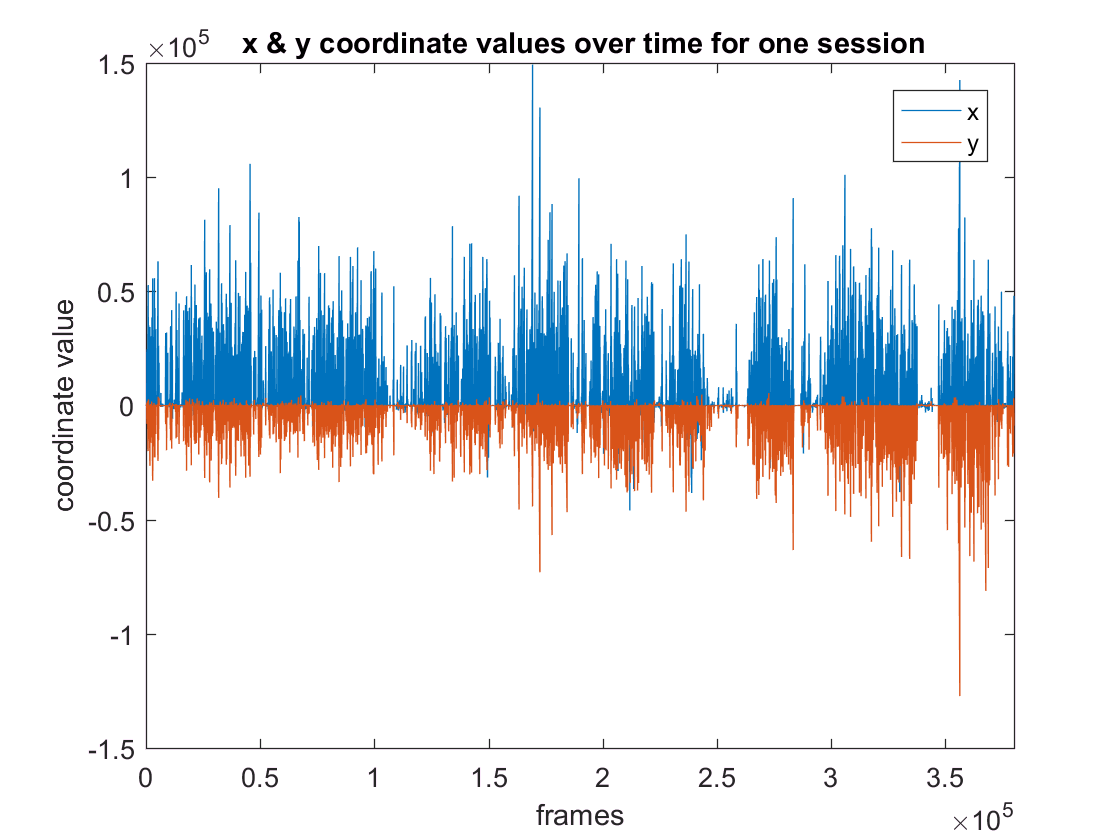

% what I want to focus on in this block is first getting the allStop & allResp frames 
% "stitched back" in order of time/trial presentation,
% then I want to put them in same time reference as imaging frames & plot on same plot

% for one SESSION, concatenate X values & Y values from each TRIAL
% ALL RESP

clear allXCoordinatesAllTrialsOneSessAllStop 
clear allYCoordinatesAllTrialsOneSessAllStop 
clear allXCoordinatesAllTrialsOneSessAllResp 
clear allYCoordinatesAllTrialsOneSessAllResp 
clear XCoordinatesStopAndRespFramesAlltrials 
clear YCoordinatesStopAndRespFramesAlltrials

allXCoordinatesAllTrialsOneSessAllStop = []; % empty vector to store all stop x/y points from all trials in
allYCoordinatesAllTrialsOneSessAllStop = [];

allXCoordinatesAllTrialsOneSessAllResp = []; % empty vector to store all resp x/y points from all trials in
allYCoordinatesAllTrialsOneSessAllResp = [];

XCoordinatesStopAndRespFramesAlltrials = []; % to store all x coordinates in order - 1st stop, 1st resp, 2nd stop, 2nd resp etc
YCoordinatesStopAndRespFramesAlltrials = []; % same but for y

clear tr
for tr = 1:length(allStop) % for each row/trial in the allResp struct array  

    % STOP period is before response period
    % extract x & y coordinate value for each frame in tthe tr-th trial
    clear allXCoordinatesTthTrialAllStop % clear - note that there's a new number 
    % of frames/coordinates each trial
    allXCoordinatesTthTrialAllStop = allStop(tr).dx; % this is the x value at each frame during the trial
    clear allYCoordinatesTthTrialAllStop
    allYCoordinatesTthTrialAllStop = allStop(tr).dy;
    
    % now do coordinates for RESPonse period
    % extract x & y coordinate value for each frame in tthe tr-th trial
    clear allXCoordinatesTthTrialAllResp % clear - note that there's a new number 
    % of frames/coordinates each trial
    allXCoordinatesTthTrialAllResp = allResp(tr).xpos; % this is the x value at each frame during the tr_th trial 
    clear allYCoordinatesTthTrialAllResp
    allYCoordinatesTthTrialAllResp = allResp(tr).ypos;
    
    % stitch together all x cordinates in order of frames/trials
    XCoordinatesStopAndRespFramesAlltrials = [XCoordinatesStopAndRespFramesAlltrials,allXCoordinatesTthTrialAllStop,allXCoordinatesTthTrialAllResp];
    % stitch together all y cordinates in order of frames/trials
    YCoordinatesStopAndRespFramesAlltrials = [YCoordinatesStopAndRespFramesAlltrials,allYCoordinatesTthTrialAllStop,allYCoordinatesTthTrialAllResp];
    
end

% concatenate x & y coordinates for all frames:
clear allCoordinatesStopAndRespFramesAlltrials
allCoordinatesStopAndRespFramesAlltrials = [XCoordinatesStopAndRespFramesAlltrials;YCoordinatesStopAndRespFramesAlltrials];

figure
clear x_axis
x_axis = [1:length(allCoordinatesStopAndRespFramesAlltrials)];
plot(x_axis,allCoordinatesStopAndRespFramesAlltrials(1,:)) % plot x coordinates over whole session
hold on
plot(x_axis,allCoordinatesStopAndRespFramesAlltrials(2,:)) % plot y coordinates over whole session
title(' x & y coordinate values over time for one session')
xlabel('frames')
ylabel('coordinate value')
xlim([0 length(x_axis)])
legend({'x','y'})

    
numRunFramesOneSession = length(allCoordinatesStopAndRespFramesAlltrials(1,:))

numRunFramesOneSession = 380010

% here is my next question - can I put a time stamp to the cursor measurement points 
% taken at 60 Hz? I think so, with allStop/Resp.frameT
% I guess just do the same code as above just with a different field in the struct?
% then concatenate?

% GETting all TIME STAMPS for CURSOR MEASUREMENTS (60 hz)

% for one SESSION, concatenate X values & Y values from each TRIAL
% ALL RESP

clear timeStampsTthTrialAllStop 
clear timeStampsTthTrialAllResp

clear timeStampsStopAndRespFramesAlltrials 

timeStampsStopAndRespFramesAlltrials = []; % to store all time stamps coordinates in order - 1st stop, 1st resp, 2nd stop, 2nd resp etc

clear tr % for each trial trial
for tr = 1:length(allStop) % for each row/trial in the struct array  

    % STOP period is before response period
    % extract time stamps
    clear timeStampsTthTrialAllStop % clear - note that there's a new number 
    % of frames/coordinates each trial
    timeStampsTthTrialAllStop = allStop(tr).frameT; % this is the time of each frame during the trial
    
    % now do coordinates for RESPonse period
    clear timeStampsTthTrialAllResp % clear - note that there's a new number 
    % of frames/coordinates each trial
    timeStampsTthTrialAllResp = allResp(tr).frameT; % this is the time point at each frame during the tr_th trial 
    
    % stitch together all x cordinates in order of frames/trials
    timeStampsStopAndRespFramesAlltrials = [timeStampsStopAndRespFramesAlltrials,timeStampsTthTrialAllStop,timeStampsTthTrialAllResp];
     
end

size_of_timeStampsStopAndRespFramesAlltrials = size(timeStampsStopAndRespFramesAlltrials)

size_of_timeStampsStopAndRespFramesAlltrials =            1      380010


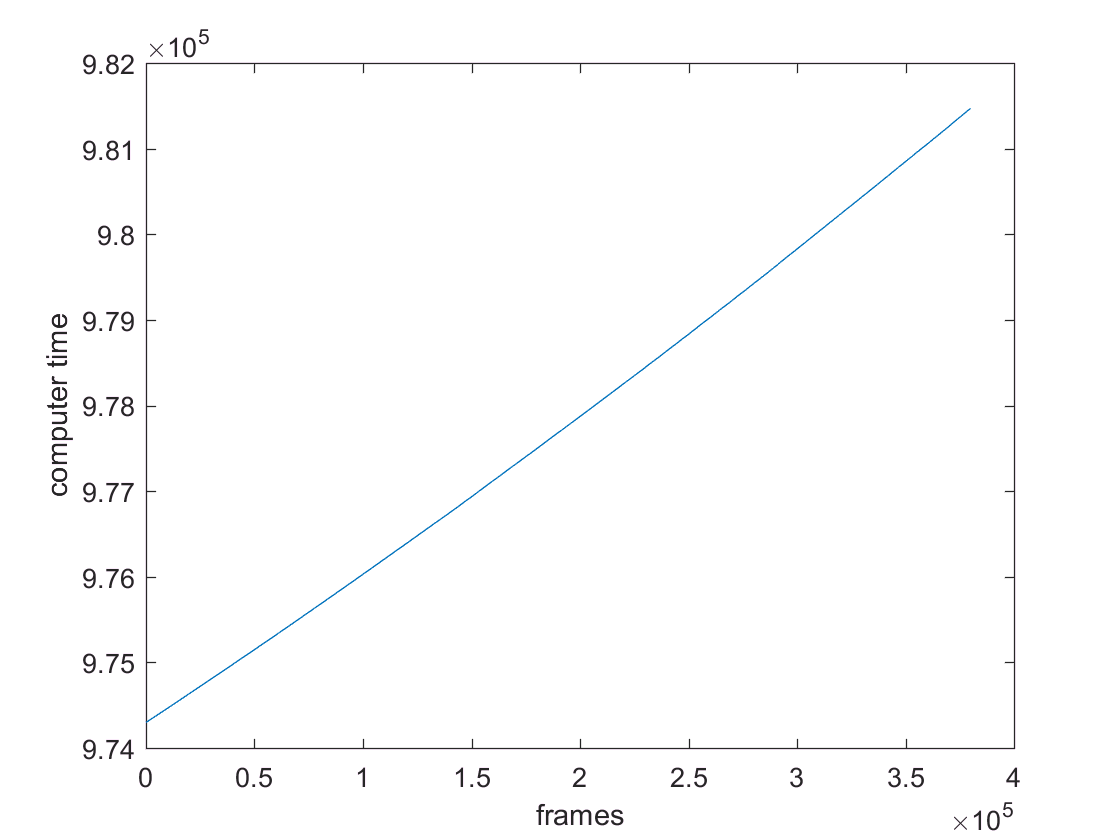


figure
plot(timeStampsStopAndRespFramesAlltrials)
ylabel('computer time')
xlabel('frames')

% ok so now, let's put both timeStampsStopAndRespFramesAlltrials & frameT in 
% time that is relative to the first frame of the trial - in this case, allStop.frameT(1)

% LOAD MAPS FILE w/ALLSTOP/RESP, FRAME T, etc

% this is the very first frames of the very first trial of the session
% (stim could come a few frames later or right away - or, no, stim should be first 
% cuz it sends the TTL signal...):

t0 = allStop(1).frameT(1); % 1st frame for 1st trial 

clear ts
% for each time stamp
for ts = 1:length(timeStampsStopAndRespFramesAlltrials)
    
    % subtract t0 so that time is relative to 1st frame onset
    timeStampsStopAndRespFramesAlltrialsMinusT0(1,ts) = timeStampsStopAndRespFramesAlltrials(ts)-t0; % units is seconds I beleive

end 

numTimeStampsStopAndRespFramesAllTrialsMinusT0 = size(timeStampsStopAndRespFramesAlltrialsMinusT0)


% based on existing lab code where frameT(1) and allStop(1).frameT(1) are both used
% as a zero point/value to subtract from each frame, I guess we are assuming that 
% the first imaging frame & first monitor frame happen at the same time? 
% idk why we would assume that when they don't have the same timestamp in cell 1...
% update... I actually think frameT 1st time stamp was greater than allStop.frameT(1),

% DEFINE FRAMET
% redefine imaging fraems so that 1st frame is t = zero for imaging frames
% Q SOULD it be FRAMET - t0 ???
% -> we set it to zero for onsets calulation...
frameTMinusT0 = frameT-frameT(1); % in seconds
frameTMinusT0 = frameTMinusT0';

numImagingFramesAllTrials = size(frameTMinusT0)
imagingFramesTimesSix = length(frameTMinusT0)*6

% SO, now, I can use timeStampsStopAndRespFramesAlltrialsMinusT0 as my x axis for 
% plotting coordinates, 
% and I can use frameTMinusT0 as the x axis for dfofV1Point (made in crop script)

dfofV1PointAndTimeStamps = [dfofV1Point;frameTMinusT0];
allCoordinatesStopAndRespFramesAlltrialsAndTimeStamps = [allCoordinatesStopAndRespFramesAlltrials;timeStampsStopAndRespFramesAlltrialsMinusT0];


neuralTrace = dfofV1PointAndTimeStamps(1,:);
imagingTimePoints = dfofV1PointAndTimeStamps(2,:);

xCoordinates = allCoordinatesStopAndRespFramesAlltrialsAndTimeStamps(1,:);
yCoordinates = allCoordinatesStopAndRespFramesAlltrialsAndTimeStamps(2,:);
coordinateTimePoints = allCoordinatesStopAndRespFramesAlltrialsAndTimeStamps(3,:);


figure
plot(imagingTimePoints,neuralTrace)
xlim([0 max(imagingTimePoints)+10])
hold on
plot(coordinateTimePoints,xCoordinates)
xlim([0 max(imagingTimePoints)+10])




% ONSET CHUNKS STUFF

% DEFINE FRAMET
% redefine imaging fraems so that 1st frame is t = zero for imaging frames
frameTminusT0 = frameT-frameT(1); % in seconds
% ^ This frameT is different then framT which are a field of allResp or allStop!
% this frameT is imaging

% SELECT ONSET FRAME CHUNKS
% you need to have done the 'CROP' step first because that's where dfCROP gets made

% making variable 'onset' - seconds relative to trial onset
% monitor frame rate = 60Hz, 
% trial onset = "start of stop"

clear onsets
clear i 

% making stimulus onset times relative to 1st trial onset

% take the first frame after "the mouse stops" for the FIRST time 
% (1st trial onset) - make that t = 0 for monitor time
t0 = allStop(1).frameT(1); % 1st frame for 1st trial 

for i = 1:length(allResp) % I think response period is when the stim comes on until mouse answers
    % get the first frame after the stimulus comes on, subtract
    % t0, the time of the first trial onset. So all stim onsets 
    % are realtive to 1st trial onset
    onsets(i) = allResp(i).frameT(1)-t0; % onsets is in seconds
    
end % now you have a list of the first frames during the resposne period
% in time that is relative to when the very FIRST trial started/"mouse stoppoed the ball"

display('size of onsets var =')
size(onsets)

% % for sessions where frameT stops before stim ONLY
% realNumTrials = 1949;  % don't know any other way to figure out how 
% % many trials frameT corresponds to other than running
% % onsetFrame code and seeing where is stops...
% onsets = onsets(1,1:realNumTrials);
% size(onsets)

% picking pre & post frames
numPreStimFrames = 4;
numPostStimFrames = 18;

% SELECT ONLY trials that have num pre sitm & num post stim frames around them
idxOnsetsMoreThan = find(onsets>numPreStimFrames);
idxOnsetsCanAdd = find(onsets+numPostStimFrames<max(onsets));
% for use later to index into only
idxOnsetsMeetBothCriteria = intersect(idxOnsetsMoreThan,idxOnsetsCanAdd);
onsets = onsets(idxOnsetsMeetBothCriteria);
size(onsets)

% making variable 'onsetFrame', gets the index for the 1st imaging 
% frame after the stimulus onset
clear onsetFrame
clear i

% collecting the index of the first imaging frame that follows each stim onset
for i = 1:length(onsets); % for each stim onset time/frame
    onsetFrame(i) = find(diff(frameT>onsets(i))); % onsetFrame is the frame index for the 
    % imaging frame frame that matches up with the onset of the stim (onsets(i)) 
end
size(onsetFrame)

% % making variable 'onsetDf'
% using onsetFrames to index into dFcrop
% & take 'chunks' of video around each stim onset
clear i
clear onsetDf
for i = 1:length(onsetFrame)
    % then select only the imaging frames right before & after the onset imaging frame of each stim
    onsetDf(:,:,:,i) = dfCROP(:,:,onsetFrame(i)-numPreStimFrames:onsetFrame(i)+numPostStimFrames);
end
size(onsetDf)
